## encoder

### part 1

global SAMPLEPERSEC;
SAMPLEPERSEC = 100;
characters = ['a':'z', ' ', '.', ',', '!', '"', ';'];

Mapset = cell(32,2);

for i = 1:length(characters)
    Mapset{i,1} = characters(i);
    Mapset{i,2} = dec2bin(i-1,5); 
end
Mapset

Mapset = 32×2 cell array
    {'a'}    {'00000'}
    {'b'}    {'00001'}
    {'c'}    {'00010'}
    {'d'}    {'00011'}
    {'e'}    {'00100'}
    {'f'}    {'00101'}
    {'g'}    {'00110'}
    {'h'}    {'00111'}
    {'i'}    {'01000'}
    {'j'}    {'01001'}
    {'k'}    {'01010'}
    {'l'}    {'01011'}
    {'m'}    {'01100'}
    {'n'}    {'01101'}
    {'o'}    {'01110'}
    {'p'}    {'01111'}
    {'q'}    {'10000'}
    {'r'}    {'10001'}
    {'s'}    {'10010'}
    {'t'}    {'10011'}
    {'u'}    {'10100'}
    {'v'}    {'10101'}
    {'w'}    {'10110'}
    {'x'}    {'10111'}
    {'y'}    {'11000'}
    {'z'}    {'11001'}
    {' '}    {'11010'}
    {'.'}    {'11011'}
    {','}    {'11100'}
    {'!'}    {'11101'}


- `SAMPLEPERSEC` تعداد نمونه‌ها در هر ثانیه را تنظیم می‌کند.

- `characters` شامل کاراکترهای قابل کدگذاری است.

- `Mapset` شامل کاراکترها و معادل دودویی ۵ بیتی آن‌ها است.

### part 2

در این بخش، روند کدگذاری پیام به صورت زیر انجام می‌شود:

- ابتدا یک جدول `Mapset` ایجاد می‌شود که هر کاراکتر از پیام ورودی (مثلاً حروف الفبا، فواصل و علائم نگارشی) به کد دودویی معادل خود نگاشت می‌شود. این کار برای تبدیل پیام به یک رشته دودویی انجام می‌شود.

- سپس، پیام ورودی به رشته‌ای از کدهای دودویی تبدیل می‌شود. این فرآیند با استفاده از `Mapset` انجام می‌شود تا هر کاراکتر از پیام به معادل دودویی خود تبدیل شود.

- پس از کدگذاری، پیام به بخش‌های کوچکتر تقسیم می‌شود. این تقسیم‌بندی بر اساس یک پارامتر به نام `transmission_speed` انجام می‌شود که طول هر بخش را مشخص می‌کند. این بخش‌ها برای پردازش و ارسال راحت‌تر آماده می‌شوند.

- سپس، هر بخش دودویی به یک سیگنال سینوسی تبدیل می‌شود. برای هر بخش دودویی، یک سیگنال سینوسی خاص تولید می‌شود که نماینده آن بخش از پیام است.

- در نهایت، تمامی سیگنال‌ها که هرکدام نمایانگر یک بخش از پیام هستند، به یک سیگنال پیوسته ترکیب می‌شوند. این سیگنال پیوسته در نهایت به عنوان خروجی برای ارسال پیام به سیستم گیرنده استفاده می‌شود.

در کل، روند کدگذاری پیام به این صورت است که ابتدا پیام به کد دودویی تبدیل می‌شود، سپس به بخش‌های کوچکتر تقسیم و در نهایت به سیگنال‌های سینوسی برای ارسال تبدیل می‌شود.

function encodedText = encodeTextWithMapset(Mapset, text)

tmp_encode = '10011001001001010011'

    % split code and char
    characters = [Mapset{:, 1}];
    codes = Mapset(:, 2);

    % map to char index
    [tmp, idx] = ismember(text, characters);
    
    % encode
    encodedText = strjoin(codes(idx), '');
end

tmp_encode = encodeTextWithMapset(Mapset, 'test')

- کاراکترهای ورودی را به رشته دودویی معادل آن‌ها بر اساس `Mapset` تبدیل می‌کند.

- از تابع `ismember` برای یافتن اندیس کاراکترها استفاده می‌شود.

- نتیجه نهایی رشته دودویی ترکیب‌شده است.

function semgments = segment_massage(transmission_speed, binary_message)

tmp_segments = 1×7 cell array
    {'100'}    {'110'}    {'010'}    {'010'}    {'010'}    {'100'}    {'11'}


    semgments = {};
    for i = 1:transmission_speed:strlength(binary_message)
        if i + transmission_speed - 1 <= strlength(binary_message)
            segment = binary_message(i:i+transmission_speed-1);
        else
            segment = binary_message(i:end);
        end
       semgments{end+1} = segment;
    end
end

tmp_segments = segment_massage(3, tmp_encode)

- پیام دودویی را به بخش‌هایی با طول `transmission_speed` تقسیم می‌کند.

- اگر طول پیام کامل نباشد، بخش آخر کوتاه‌تر خواهد بود.

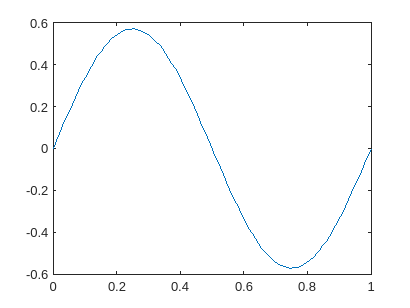

function signal = binaryToSignal(segment, t, transmission_speed)
    max_value = 2^transmission_speed - 1;

    signal = zeros(size(t));

    for i = 0:max_value
        if strcmp(dec2bin(i, transmission_speed), segment)
            signal = (i / max_value) * sin(2 * pi * t);
        end
    end
end

tmp_x = linspace(0, 1, SAMPLEPERSEC);
plot(tmp_x, binaryToSignal(tmp_segments(1), tmp_x, 3));

- بخش دودویی ورودی را به سیگنال سینوسی تبدیل می‌کند.

- مقدار سیگنال بر اساس مقدار دودویی نسبت به حداکثر مقدار ممکن تنظیم می‌شود.

- از تابع `strcmp` برای مقایسه رشته‌ها استفاده می‌کند.

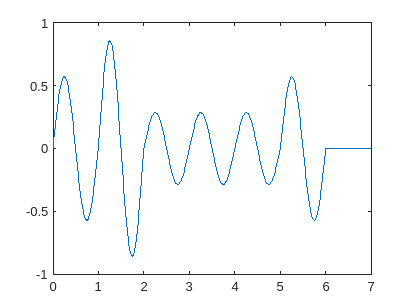

function encoded_message = convert_to_signal(semgments, transmission_speed)
    global SAMPLEPERSEC;
    t = linspace(0, 1, SAMPLEPERSEC);


    encoded_message = zeros(1, length(t) * length(semgments));

    for i = 1:length(semgments)
       segment = semgments{i};
       signal = binaryToSignal(segment, t, transmission_speed);
        start_idx = (i-1)*length(t) + 1;
        end_idx = i*length(t);
        encoded_message(start_idx:end_idx) = signal;
    end
end

tmp_signal = convert_to_signal(tmp_segments, 3);
tmp_x = linspace(0, length(tmp_signal)/SAMPLEPERSEC, length(tmp_signal)); 
plot(tmp_x ,tmp_signal);

- تمام بخش‌های دودویی را به سیگنال‌های سینوسی تبدیل و در یک سیگنال پیوسته قرار می‌دهد.

- از `SAMPLEPERSEC` برای تنظیم تعداد نمونه‌ها استفاده می‌کند.

- سیگنال نهایی از ترکیب تمامی بخش‌ها ساخته می‌شود.

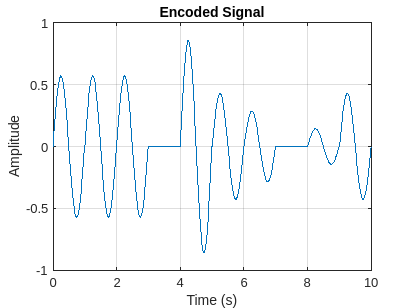

function encoded_message = coding_amp(message, transmission_speed, Mapset)
    message = char(message);
    binary_message = encodeTextWithMapset(Mapset,message);

    semgments = segment_massage(transmission_speed, binary_message);


    encoded_message = convert_to_signal(semgments, transmission_speed);

end

- پیام ورودی را به کد دودویی تبدیل می‌کند.

- پیام دودویی را به بخش‌های کوچک‌تر تقسیم می‌کند.

- سیگنال پیوسته را با استفاده از بخش‌های دودویی تولید می‌کند.

message = 'signal';
speed = 3;
encoded_message = coding_amp(message, speed, Mapset);

t = linspace(0, length(encoded_message)/SAMPLEPERSEC, length(encoded_message)); 
plot(t, encoded_message);
xlabel('Time (s)');
ylabel('Amplitude');
title('Encoded Signal');
grid on;

- سیگنال کدگذاری‌شده رسم می‌شود.

- برچسب‌های زمان و دامنه تنظیم شده‌اند.

- `grid on` برای نمایش بهتر نمودار فعال می‌شود.

### part 3

این کد پیام "signal" را با سرعت‌های ارسال اطلاعات ۱، ۲ و ۳ بیت بر ثانیه رمزگذاری کرده و سیگنال‌های رمزگذاری‌شده را در نمودارهای جداگانه بر اساس زمان رسم می‌کند.

message = 'signal';
speeds = [1, 2, 3];

for i = 1:length(speeds)
    speed = speeds(i);
    encoded_message = coding_amp(message, speed, Mapset);
    
    figure;
    t = linspace(0, length(encoded_message)/SAMPLEPERSEC, length(encoded_message)); 
    plot(t, encoded_message);
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(sprintf('Encoded Signal for Message "signal" at Speed %d bits/sec', speed));
    grid on;
end